# Preprocessing the docuement network data to extract the linkages and the content information

clear all
close all
clc
load('cora_raw');

Check the unique paper id set

paper_unique_id = unique(paper_id);
if length(paper_id) == length(paper_unique_id)
    s = sprintf('The paper id is unique and no duplications');
    disp(s)
else
    error('repetitive docuemnts in the content');
end

The paper id is unique and no duplications


check if the linkages' paper id are in the content

cite_set = unique(cite_id);
cited_set = unique(cited_id);

cite_indicator = ismember(cite_set, paper_id);
cited_indicator = ismember(cited_set, paper_id);

if all(cite_indicator) & all(cited_indicator)
    s = sprintf('Test passed for the linkages'' network');
    disp(s);
else 
    error('linkages'' docuement set is not included in the content');
end

Test passed for the linkages' network


Construct the linkage network matrix C

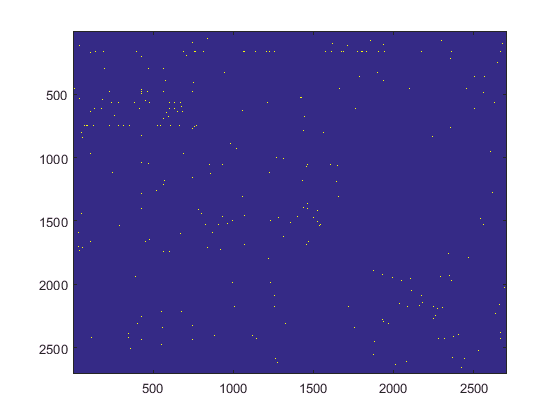

[~, cite_index] = ismember(cite_id, paper_id);
[~, cited_index] = ismember(cited_id, paper_id);
C = sparse(cite_index, cited_index, ones(length(cite_id),1), length(paper_id), length(paper_id));
C = C | C.';
imagesc(C);

The W matr

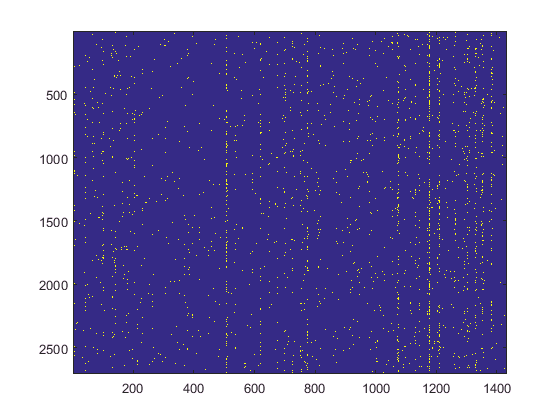

W = cora_W;
imagesc(W);

Save the dataset

save 'cora.mat' 'C' 'W' 'paper_id' 'paper_classname'